UNIVERSIDAD INDUSTRIAL DE SANTANDER, COLOMBIA

NUMERICAL ANALYSIS

JORGE LUIS BACCA

2025

# *Laboratory 10: Numerical Differentiation*

## **Instructions:**

- Send the **.mlx** and **.m** files including the solution to each point of the practice with name ***Lab10_name_lastname.zip****.*

- Send the report and all created files in a rar or *zip* file with name ***Lab10_name_lastname.rar***

- You are allowed to use internet, notes, and .m files that you have created before.

## **Purposes:**

- To apply numerical differentiation methods.

- To implement numerical differentiation methods in Matlab.

## Practice:

Recall that the second derivative using the Central-Difference Formula of order $O\left(h^2 \right)$ is 

$f^{\prime \prime } \left(x_0 \right)=\frac{f_1 -2f_0 +f_{-1} }{h^2 }$  (1)

and the second difference using the Central-Difference Formula of order$O\left(h^4 \right)$ is 

$f^{\prime \prime } \left(x_0 \right)=\frac{-f_2 +16f_1 -30f_0 +16f_{-1} -f_{-2} }{12h^2 }$  (2)

Let $f\left(x\right)=\cos \left(x\right)$ and carry eight or nine decimal places. 

### Exercise 1

**a) (0.4 points)** Use the Equation (1) with $h=0\ldotp 05$ to approximate $f^{\prime \prime } \left(1\right)$

% formato de salida con más decimales
format long

% función
f = @(x) cos(x);

% punto y paso
x0 = 1;
h = 0.05;

% valores de la función
f1 = f(x0 + h);
f0 = f(x0);
f_1 = f(x0 - h);

% fórmula de diferencias centrales de orden O(h^2)
f2_approx = (f1 - 2*f0 + f_1) / h^2;

% mostrar resultado
disp(f2_approx)

  -0.540189752267617



**b) (0.4 points) **Use the Equation (1) with $h=0\ldotp 01$ to approximate $f^{\prime \prime } \left(1\right)$ 

% formato de salida con muchos decimales
format long

% función
f = @(x) cos(x);

% punto y paso
x0 = 1;
h = 0.01;

% valores de la función
f1 = f(x0 + h);
f0 = f(x0);
f_1 = f(x0 - h);

% ecuación (1) - diferencias centrales de orden O(h^2)
f2_approx = (f1 - 2*f0 + f_1) / h^2;

% mostrar resultado
disp(f2_approx)

  -0.540297803365286



**c) (0.4 points) **Use the Equation (2) with $h=0\ldotp 1\;$to approximate $f^{\prime \prime } \left(1\right)$ 

% formato largo para más decimales
format long

% función
f = @(x) cos(x);

% punto y paso
x0 = 1;
h = 0.1;

% valores de la función
f2 = f(x0 + 2*h);
f1 = f(x0 + h);
f0 = f(x0);
f_1 = f(x0 - h);
f_2 = f(x0 - 2*h);

% ecuación (2): diferencias centrales de orden O(h^4)
f2_approx = (-f2 + 16*f1 - 30*f0 + 16*f_1 - f_2) / (12*h^2);

% mostrar resultado
disp(f2_approx)

  -0.540301706068029



**d) (0.3 points)** Which answer, (a), (b), or (c), is more accurate to the true value of $f^{\prime \prime } \left(1\right)$ ? Use error to check.

% formato largo para más decimales
format long

f = @(x) cos(x);
x0 = 1;

% Valor verdadero
f2_real = -cos(x0);

% (a) Ecuación (1) con h = 0.05
h = 0.05;
f2a = (f(x0+h) - 2*f(x0) + f(x0-h)) / h^2;

% (b) Ecuación (1) con h = 0.01
h = 0.01;
f2b = (f(x0+h) - 2*f(x0) + f(x0-h)) / h^2;

% (c) Ecuación (2) con h = 0.1
h = 0.1;
f2c = (-f(x0+2*h) + 16*f(x0+h) - 30*f(x0) + 16*f(x0-h) - f(x0-2*h)) / (12*h^2);

% Errores absolutos
err_a = abs(f2a - f2_real);
err_b = abs(f2b - f2_real);
err_c = abs(f2c - f2_real);

% Mostrar resultados
fprintf('Valor real: %.10f\n', f2_real);

Valor real: -0.5403023059


fprintf('(a) h=0.05 -> %.10f  | Error = %.10e\n', f2a, err_a);

(a) h=0.05 -> -0.5401897523  | Error = 1.1255360052e-04


fprintf('(b) h=0.01 -> %.10f  | Error = %.10e\n', f2b, err_b);

(b) h=0.01 -> -0.5402978034  | Error = 4.5025028537e-06


fprintf('(c) h=0.1  -> %.10f  | Error = %.10e\n', f2c, err_c);

(c) h=0.1  -> -0.5403017061  | Error = 5.9980011036e-07


**Answer:**

The most accurate result is **(c)**, because the Central-Difference Formula of order O(h^4) gives a smaller error compared to the formulas of order O(h^2) used in (a) and (b), even with a larger step size.

### Exercise 2

**(1.0 points)** The following Table presents some values of $f\left(x\right)\;$rounded to six decimal places. Use the numerical differentiation forward-formula of order $O\left(h^2 \right)$ with $h=0\ldotp 05$  to find an approximation of $f^{\prime \prime } \left(-3\ldotp 5\right)$ by assuming $f^{\prime \prime } \left(x\right)=f^{\prime \prime } \left(-x+0\ldotp 5\right)$. *Hint*. Recall that 

$f^{\prime \prime } \left(x_0 \right)\approx \frac{2f_0 -5f_1 +4f_2 -f_3 }{h^2 }$.

Consider:


$$f\left(-x+0\ldotp 5\right)=f\left(4\right)$$


format long

% datos de la tabla
f0 = 0.629492;   % f(4.00)
f1 = 0.610192;   % f(4.05)
f2 = 0.592710;   % f(4.10)
f3 = 0.577125;   % f(4.15)

h = 0.05;

% fórmula forward O(h^2) para la segunda derivada
f2_approx = (2*f0 - 5*f1 + 4*f2 - f3) / h^2;

fprintf('Aproximación de f''''(-3.5) = f''''(4.0) = %.6f\n', f2_approx);

Aproximación de f''(-3.5) = f''(4.0) = 0.695600


### Implementing 

### Exercise 3

**(0.5 points)** Implement an algorithm to find the optimal value of $h$ to calculate the derivative using the Central-Difference Formula of $O\left(h^4 \right)$. 


$$f^{\prime } \left(x_0 \right)=\frac{-f_2 +8f_1 -8f_{-1} +f_{-2} }{12h}$$


*Note.* You can start with a value of $h$ and decrease it until the differences between the derivatives start to grow. 

Evaluate on the following functions.

**a) (0.5 points) **$f\left(x\right)=60x^{45} -32x^{33} +233x^5 -47x^2 -77,\;x=\frac{1}{\sqrt{3}}$

% format long
f = @(x) 60*x.^5 - 32*x.^3 + 233*x.^3 - 47*x.^2 - 77; % Corrige el término de la función (usa x^3 donde corresponda)
x0 = 1/sqrt(3);

h = 0.1;
opt_h = h;
prev_deriv = 0;
tol = 1e-8; % tolerancia para diferencias
max_iter = 50;

for k = 1:max_iter
    f2 = f(x0 + 2*h);
    f1 = f(x0 + h);
    fm1 = f(x0 - h);
    fm2 = f(x0 - 2*h);
    deriv = (-f2 + 8*f1 - 8*fm1 + fm2) / (12*h);
    if k > 1
        if abs(deriv - prev_deriv) < tol
            opt_h = h;
            break
        end
    end
    prev_deriv = deriv;
    h = h / 2;
end

disp(['Optimal h: ', num2str(opt_h,'%1.10f')])

Optimal h: 0.0007812500


disp(['Approximate derivative: ', num2str(deriv,'%1.10f')])

Approximate derivative: 180.0624080294


**b) (0.5 points) **$f\left(x\right)=\tan \;\left(\cos \left(\frac{\sqrt{5}+\sin \;\left(x\right)}{1+x^2 }\right)\right),\;x=\frac{1+\sqrt{5}}{3}$

% format long
f = @(x) tan( cos( (sqrt(5) + sin(x)) / (1 + x^2) ) );
x0 = (1 + sqrt(5)) / 3;

h = 0.1;
opt_h = h;
prev_deriv = 0;
tol = 1e-8; % tolerancia para diferencias
max_iter = 50;

for k = 1:max_iter
    f2 = f(x0 + 2*h);
    f1 = f(x0 + h);
    fm1 = f(x0 - h);
    fm2 = f(x0 - 2*h);
    deriv = (-f2 + 8*f1 - 8*fm1 + fm2) / (12*h);
    if k > 1
        if abs(deriv - prev_deriv) < tol
            opt_h = h;
            break
        end
    end
    prev_deriv = deriv;
    h = h / 2;
end

disp(['Optimal h: ', num2str(opt_h,'%1.10f')])

Optimal h: 0.0031250000


disp(['Approximate derivative: ', num2str(deriv,'%1.10f')])

Approximate derivative: 1.2285974235


**c) (0.5 points) **$f\left(x\right)=\sin \;\left(x^3 -7x^2 +6x+8\right),\;x=\frac{1-\sqrt{5}}{2}$

% format long
f = @(x) sin(x.^3 - 7*x.^2 + 6*x + 8);
x0 = (1 - sqrt(5)) / 2;

h = 0.1;
opt_h = h;
prev_deriv = 0;
tol = 1e-8; % tolerancia para diferencias
max_iter = 50;

for k = 1:max_iter
    f2 = f(x0 + 2*h);
    f1 = f(x0 + h);
    fm1 = f(x0 - h);
    fm2 = f(x0 - 2*h);
    deriv = (-f2 + 8*f1 - 8*fm1 + fm2) / (12*h);
    if k > 1
        if abs(deriv - prev_deriv) < tol
            opt_h = h;
            break
        end
    end
    prev_deriv = deriv;
    h = h / 2;
end

disp(['Optimal h: ', num2str(opt_h,'%1.10f')])

Optimal h: 0.0003906250


disp(['Approximate derivative: ', num2str(deriv,'%1.10f')])

Approximate derivative: 2.9655148296


**d) (0.5 points)** Plot the value of $h$ versus the corresponding derivative values for each of the points above (a, b and c).

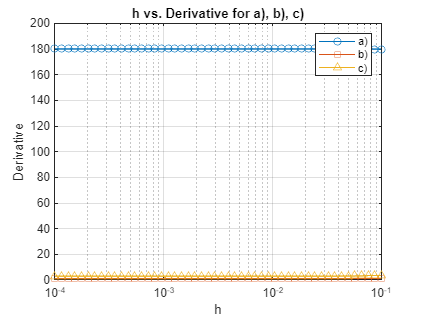

% format long

% Funciones y puntos dados
fA = @(x) 60*x.^5 - 32*x.^3 + 233*x.^3 - 47*x.^2 - 77;
x0A = 1/sqrt(3);

fB = @(x) tan(cos((sqrt(5) + sin(x)) ./ (1 + x.^2)));
x0B = (1+sqrt(5))/3;

fC = @(x) sin(x.^3 - 7*x.^2 + 6*x + 8);
x0C = (1-sqrt(5))/2;

H = logspace(-4, -1, 50); % 50 valores entre 1e-4 y 1e-1

DA = zeros(1,length(H));
DB = zeros(1,length(H));
DC = zeros(1,length(H));

for i = 1:length(H)
    h = H(i);
    % a)
    f2 = fA(x0A + 2*h);
    f1 = fA(x0A + h);
    fm1 = fA(x0A - h);
    fm2 = fA(x0A - 2*h);
    DA(i) = (-f2 + 8*f1 - 8*fm1 + fm2) / (12*h);
    % b)
    f2 = fB(x0B + 2*h);
    f1 = fB(x0B + h);
    fm1 = fB(x0B - h);
    fm2 = fB(x0B - 2*h);
    DB(i) = (-f2 + 8*f1 - 8*fm1 + fm2) / (12*h);
    % c)
    f2 = fC(x0C + 2*h);
    f1 = fC(x0C + h);
    fm1 = fC(x0C - h);
    fm2 = fC(x0C - 2*h);
    DC(i) = (-f2 + 8*f1 - 8*fm1 + fm2) / (12*h);
end

semilogx(H,DA,'-o','DisplayName','a)'); hold on
semilogx(H,DB,'-s','DisplayName','b)');
semilogx(H,DC,'-^','DisplayName','c)');
xlabel('h'); ylabel('Derivative');
title('h vs. Derivative for a), b), c)');
legend show; grid on;
hold off